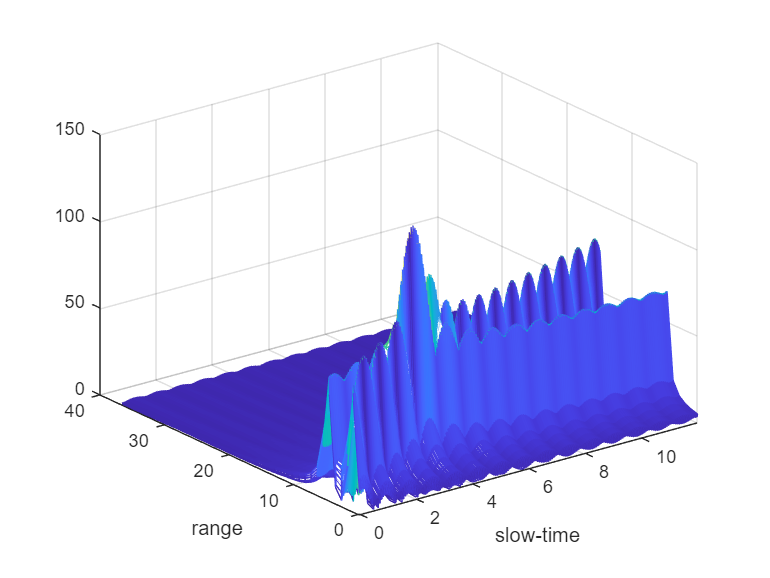

%与论文中第一点不同：FFT点数
%heart & breathing signal simulation
clc
clear
%parameter setting
fc=5.8e9;
fs=8e3;
Tchirp = 12/2400;%12s是slow-time，Tchirp是fast-time
B = 160e6;
Nc = 2400;
Ns = 80;
c = 3e8;
lamda=c/fc;



%目标生成
R_init = [5;1];%雷达与物体距离
v = [0;1.17] ;%加入一个scatter
n=0:Ns*Nc-1;
t=n.*((Nc*Tchirp)/(Ns*Nc));

%加入振动目标位移信号
xt=5.625+0.3*cos(2*pi*0.5.*t);
% xt=5.625
R_clutter=xt;

%二级参数
S = B/Tchirp;
rangeRes = c/(2*B);
Fs = Ns/Tchirp; %sampling rate
R_max = 200;
f_IFmax =  2*S*R_max/c;

%发射信号生成
Tx = exp(1i*(2*pi*fc.*(t)+pi*S.*mod(t, Tchirp).^2));

%回波信号生成
tau = 2*(R_init+v*t)./(c+v);%(c+v是与论文中不同的地方)
R_tau=R_init+v*t;
Rx = exp(1i*(2*pi*fc.*(t-tau) + S*pi.*mod((t-tau), Tchirp).^2));
Rx=sum(Rx);%回波信号
%先不加入呼吸心跳信号测量距离
IF=Tx.*conj(Rx);
IF=reshape(IF,Ns,Nc);
IF_fft=abs(fft(IF,Ns));
range_axis=linspace(0,(Ns/2-1)*rangeRes,Ns/2);%注意这里距离范围要减一，两端植树问题
slow_time_axis=linspace(0,(Nc-1)*Tchirp, Nc);
% mesh(IF_fft(1:Ns/2,:));
mesh(slow_time_axis,range_axis,IF_fft(1:Ns/2,:));
xlabel('slow-time')
ylabel('range')

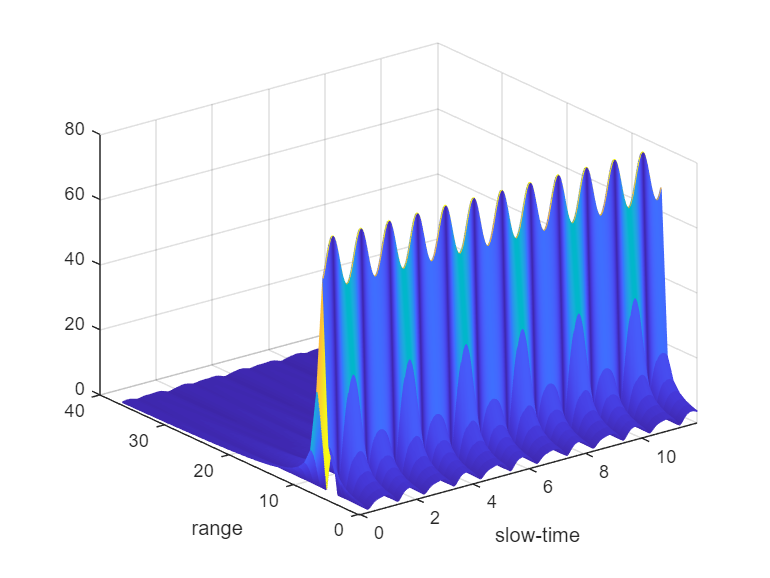

%加入振动后
v_c=0;
tau_c = 2*(R_clutter+v_c*t)./(c+v_c);%(c+v是与论文中不同的地方)
%振动和bin的关系
R_tau_c=R_clutter+v_c*t;
Rx_clutter = exp(1i*(2*pi*fc.*(t-tau_c) + S*pi.*mod((t-tau_c), Tchirp).^2));%猜想是否是距离处定义有问题
%回波信号
IF_clutter=Tx.*conj(Rx_clutter);
IF_clutter=reshape(IF_clutter,Ns,Nc);
IF_fft_c=fft(IF_clutter,Ns);%%%%%%%%%%不该取abs
range_fft=IF_fft_c(1:Ns/2,:);
mesh(slow_time_axis,range_axis,abs(IF_fft_c(1:Ns/2,:)));
xlabel('slow-time')
ylabel('range')

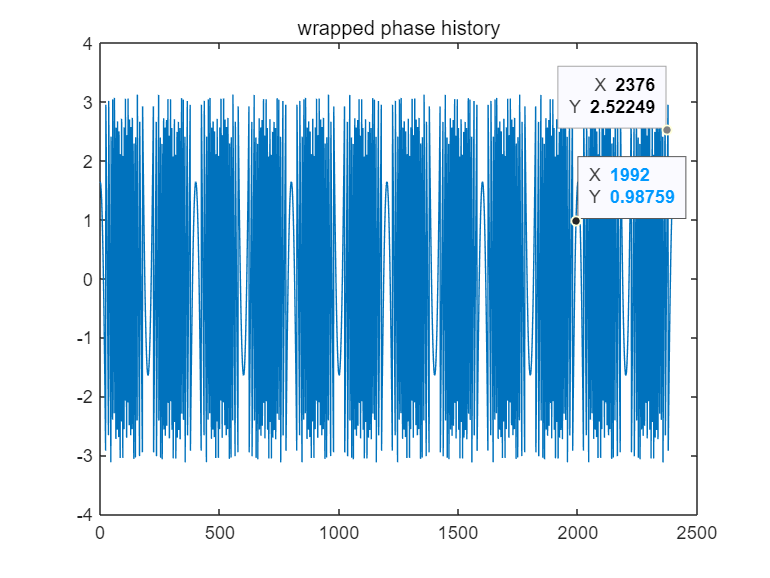

r_desired = IF_fft_c(7,:);%这里先手动让range_index=7
phi_init=atan2(imag(r_desired),real(r_desired));%此处用了反正切，以获得pi内的信息coswt+j*sinwt
phi_wrapped=phi_init;
for n=1:length(r_desired)-1
    if phi_init(1,n+1) - phi_init(1,n) > pi 
       phi_init(1,n+1) = phi_init(1,n+1) - 2*pi;
    end
    if phi_init(1,n+1) - phi_init(1,n) < -pi 
        phi_init(1,n+1) = phi_init(1,n+1) + 2*pi;
    end
end
phi_final=phi_init;
range_history=c.*phi_final/(4*pi*fc);
range_history_wrapped=c.*phi_wrapped/(4*pi*fc);
% plot(range_history,'b');
% hold on
plot(phi_wrapped);
title("wrapped phase history")

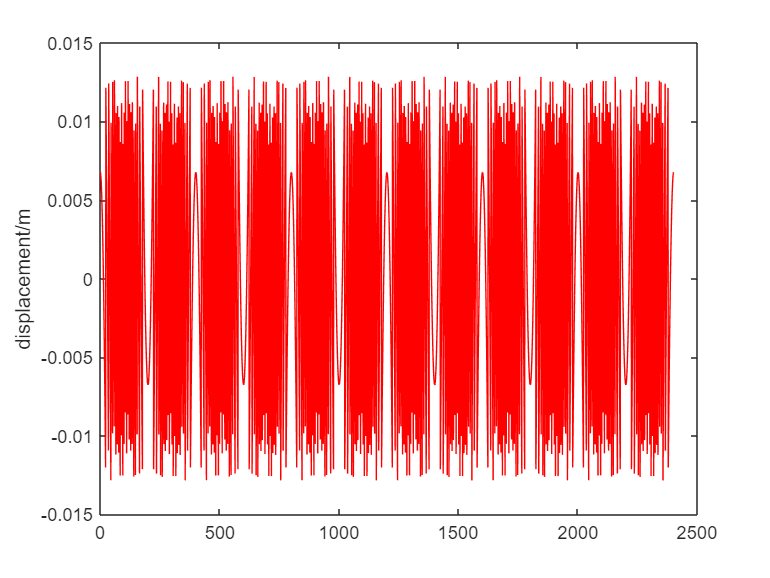

plot(range_history_wrapped,'r')
ylabel("displacement/m")

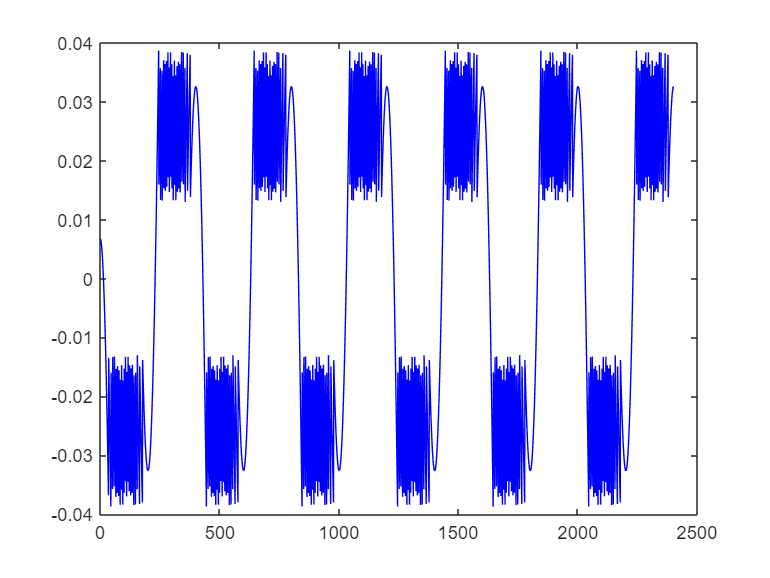

% hold off
plot(range_history,'b')